# Prediction of chaotic time series with NAR neural network

An example of a dynamic neural network with time delays and global feedback is presented in this exercise. 

The task is to design a nonlinear autoregressive (NAR) neural network for the recursive prediction of chaotic Mackay-Glass time series. 

Mackay-Glass time series represents a nonlinear (chaotic) dynamic system and we wish to construct a predictor for recursive one-step-ahead prediction.

Try different network architectures and experiment with different input delays.

2022 © Primož Potočnik ([University of Ljubljana](https://www.uni-lj.si), [Faculty of Mechanical Engineering](https://www.fs.uni-lj.si))

## Generate data

The data are generated by simulating the mathematical definition of the Mackay-Glass time series.

close all, clear all, clc, format compact

% data settings
Nt =300; % number of training samples
Nv =400; % number of validation samples

 

### Mackay-Glass time series        

### 
$$\dot{y}(t)=-by(t)+\frac{cy(t-\tau)}{1+y^{10}(t-\tau)}$$


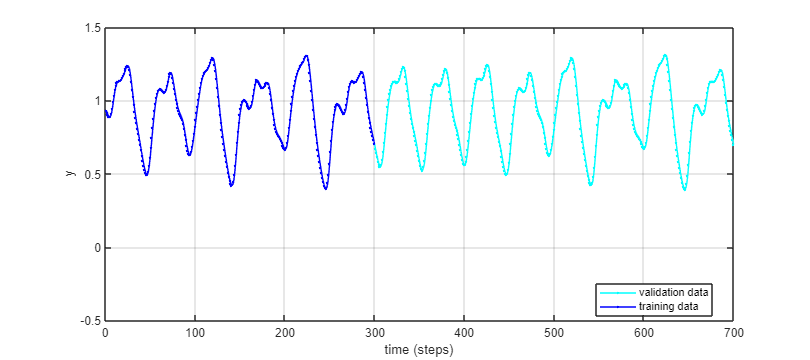

% Mackay-Glass time series parameters
b   = 0.1;
c   = 0.2;
tau = 17; 

% initialization
y = [0.9697 0.9699 0.9794 1.0003 1.0319 1.0703 1.1076 1.1352 1.1485 ...
     1.1482 1.1383 1.1234 1.1072 1.0928 1.0820 1.0756 1.0739 1.0759]';
% generate Mackay-Glass time series
for n=18:Nt+Nv+99
  y(n+1) = y(n) - b*y(n) + c*y(n-tau)/(1+y(n-tau).^10);
end
% remove initial values
y(1:100) = []; 

% plot training and validation data
figure('position',[1 60 900 400])
plot(y,'c.-')
grid on, hold on
plot(y(1:Nt),'b.-')
legend('validation data','training data','location','best')
xlabel('time (steps)')
ylabel('y')
ylim([-.5 1.5])

## Configure NAR neural network

Nonlinear autoregressive (NAR) neural network is constructed by using the MATLAB built-in function 'narnet'.

% hidden layer parameters
num_first_hidden_layer  =4; % number of neurons in the first hidden layer
num_second_hidden_layer =3; % number of neurons in the first hidden layer
% iput delays
delay_step = 6;
max_delay  = 19;

% compose input delay vector
inputDelays = 1:delay_step:max_delay;  % input delay vector

% nonlinear autoregressive neural network
net = narnet(inputDelays, [num_first_hidden_layer num_second_hidden_layer]);

## Prepare input and target time series data for network training

The data are transformed into time series (sequential vectors), and the input and target time series data are prepared for network training.

% prepare training data
yt = con2seq(y(1:Nt)');

% prepare data for network training
%   Xs : shifted inputs
%   Xi : initial input delay states
%   Ai : initial layer delay states
%   Ts : shifted targets
[Xs,Xi,Ai,Ts] = preparets(net,{},{},yt);

## Train NAR network

The network is trained using the series-parallel architecture where true output is used instead of feeding back the estimated output. The advantages of series-parallel architecture for training are:

- Training input to the feedforward network is more accurate which results in improved training accuracy

- The resulting network is purely feedforward, therefore static backpropagation can be used

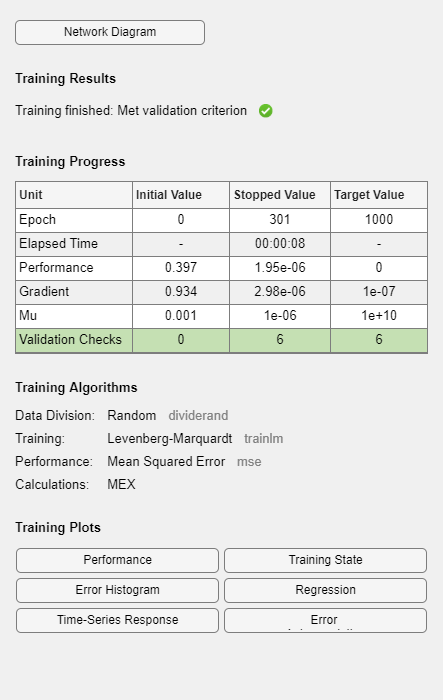

% train net with prepared training data
net = train(net,Xs,Ts,Xi,Ai);

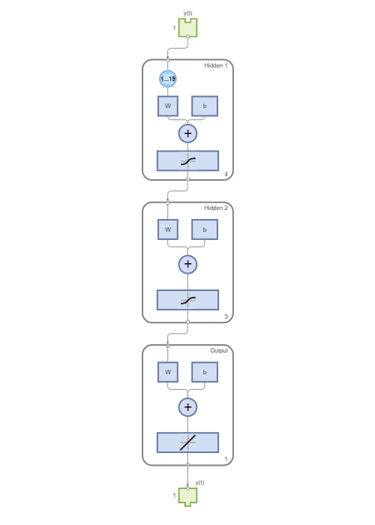

% view trained net
view(net)

## Transform network into a closed-loop NAR network

After training, the network is transformed into a parallel architecture which adds closed-loop global feedback to the network architecture. This network is suitable for the recursive prediction of time series. See the 'NARX training considerations' in the associated PowerPoint presentation.

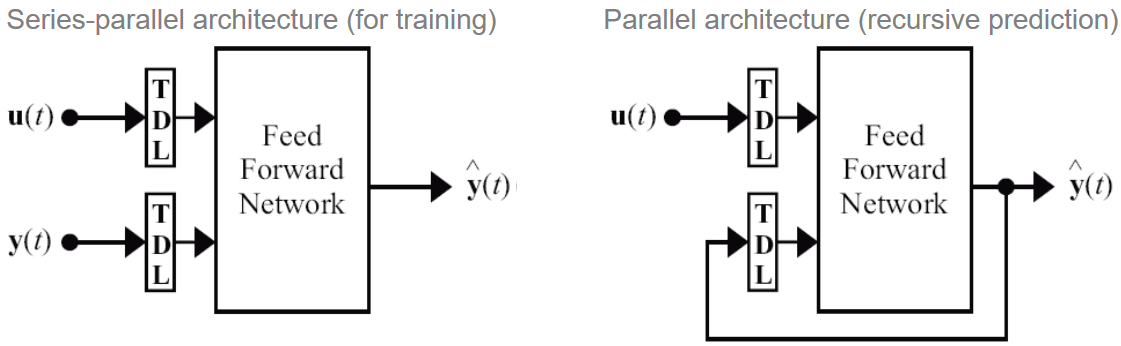

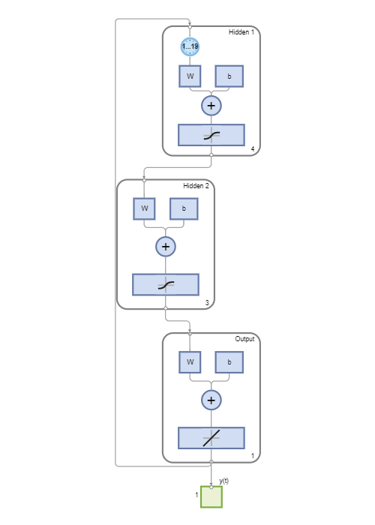

% close feedback for recursive prediction
net = closeloop(net);

% view closeloop version of a net
view(net);

## Recursive prediction on validation data

The trained network in parallel architecture is finally applied for recursive prediction of Mackay-Glass time series. Observe the prediction error on validation data to estimate how well the network completes the prediction task. Notice that short-term predictions are quite accurate, whereas later predictions are less and less accurate due to accumulated error in recursive configuration.

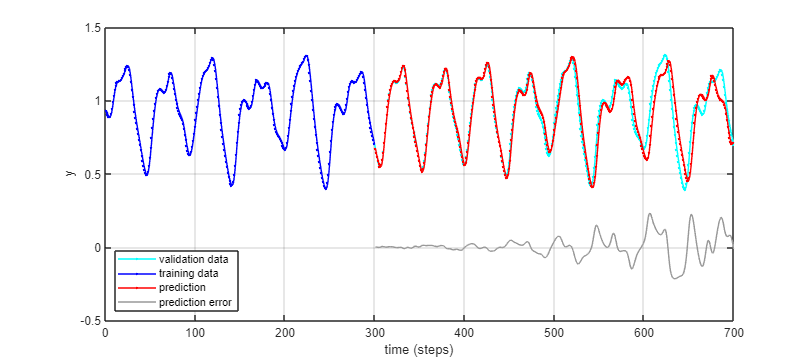

% prepare validation data
yv = con2seq(y(Nt+1:end)');

% prepare initial validation data
yini = yt(end-max(inputDelays)+1:end); % initial values from training data

% combine initial values and validation data for network simulation
[Xs,Xi,Ai] = preparets(net,{},{},[yini yv]);

% predict on validation data
predict = net(Xs,Xi,Ai);

% prepare validation data, prediction and error for plotting
Yv = cell2mat(yv); 
Yp = cell2mat(predict); 
e  = Yv - Yp;

% plot results of recursive simulation
figure(1)
plot(Nt+1:Nt+Nv,Yp,'r.-')
plot(Nt+1:Nt+Nv,e,'-','color',[.6 .6 .6])
legend('validation data','training data','prediction','prediction error','location','southwest')

% close all windows
close all force

## PowerPoint presentation

[NN5a_Dynamic_networks.pptx](matlab:open('./NN5a_Dynamic_networks.pptx'))